# DC motor simulation for Micromouse

## Define motor constants

These constans can be found in the data sheet or by doing experiments. Our values are taken from our motor [Faulhaber Series 1717006SR](https://www.faulhaber.com/fileadmin/Import/Media/EN_1717_SR_DFF.pdf).

clear                           % Clear workspace
R = 4.3;                        % Ohm
L = 65 * 10^-6;                 % H
J = 5.8 * 10^-8;                % kgm^2
lambda = 3.96 * 10^-3;          % Nm/A
I_0 = 0.046;                    % A - no load current
V_0 = 6;                        % V - no load voltage
n_0 = 14*10^3;                  % rpm - no load speed
b = lambda*I_0/(n_0 * 2*pi/60); % Nms 

## Run the Simulink/Simscape simulation

Simulink is used to model the system with blocks and some of the blocks are used from the Simscape library, such as the DC motor and rotanional motion sensor. You can watch the response by clicking the scope button.

## Controller

The contol system is shown in the picture below where ***r*** is the reference signal, ***e*** is the error in angular velocity, ***u*** is the control signal. The plant is our model we created in Simulink with the help of Simcape.

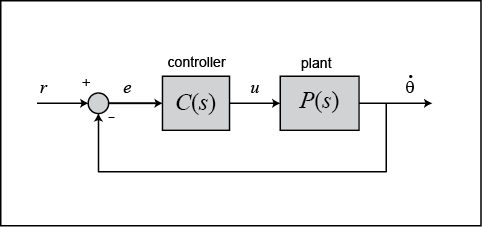

The controller is based on a root locus controll design. Måste ändra så att de är i rätt enhet!

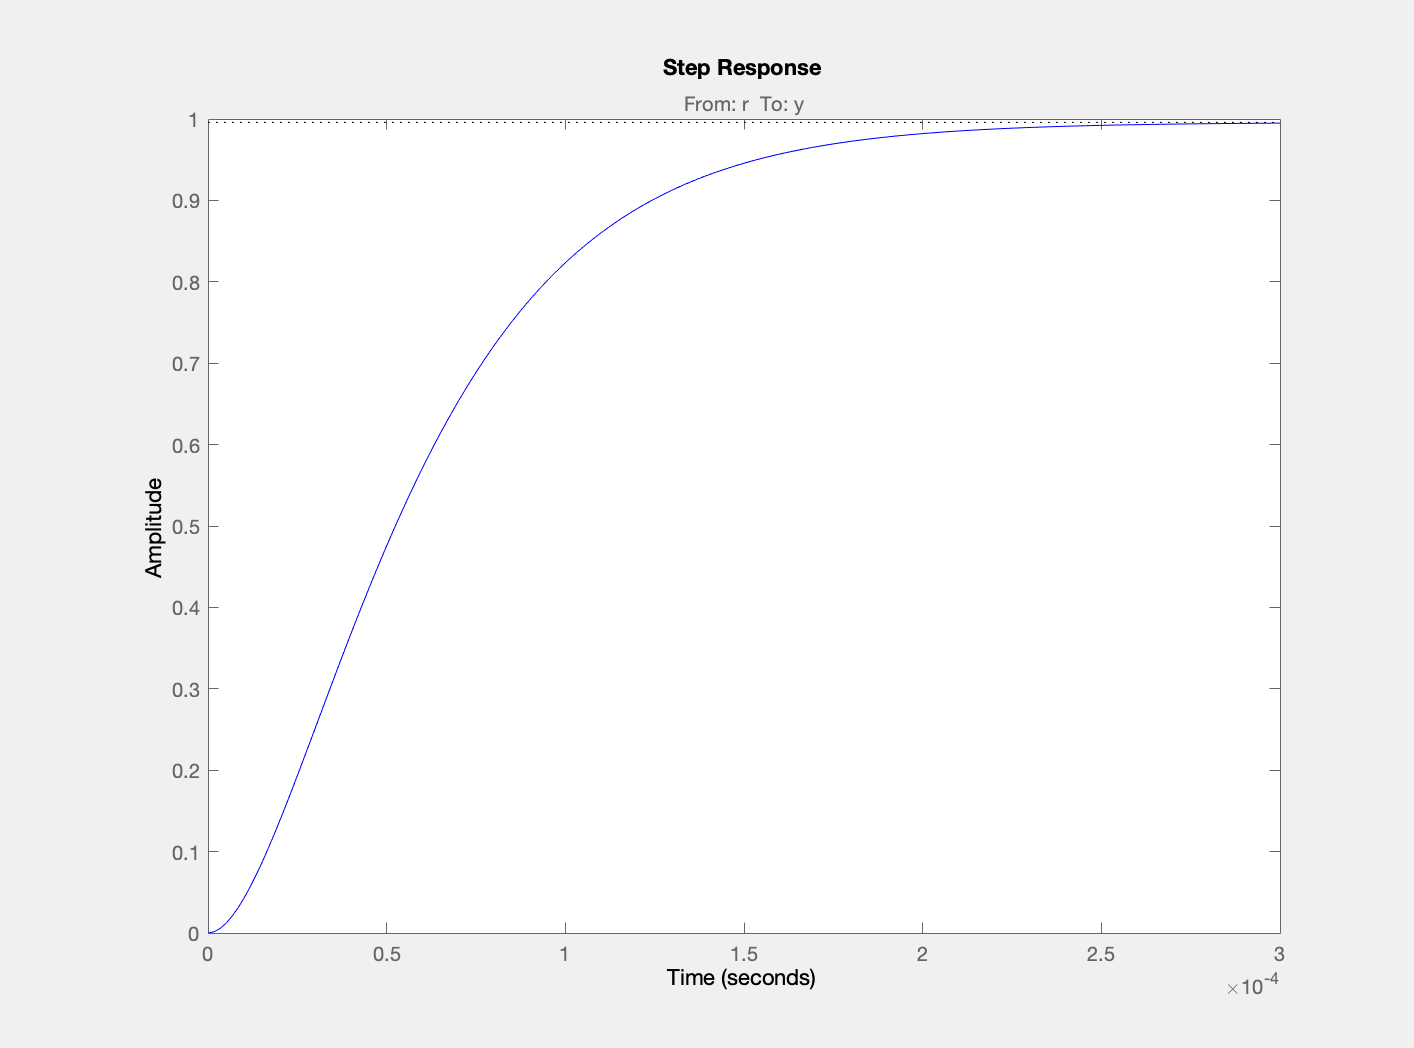

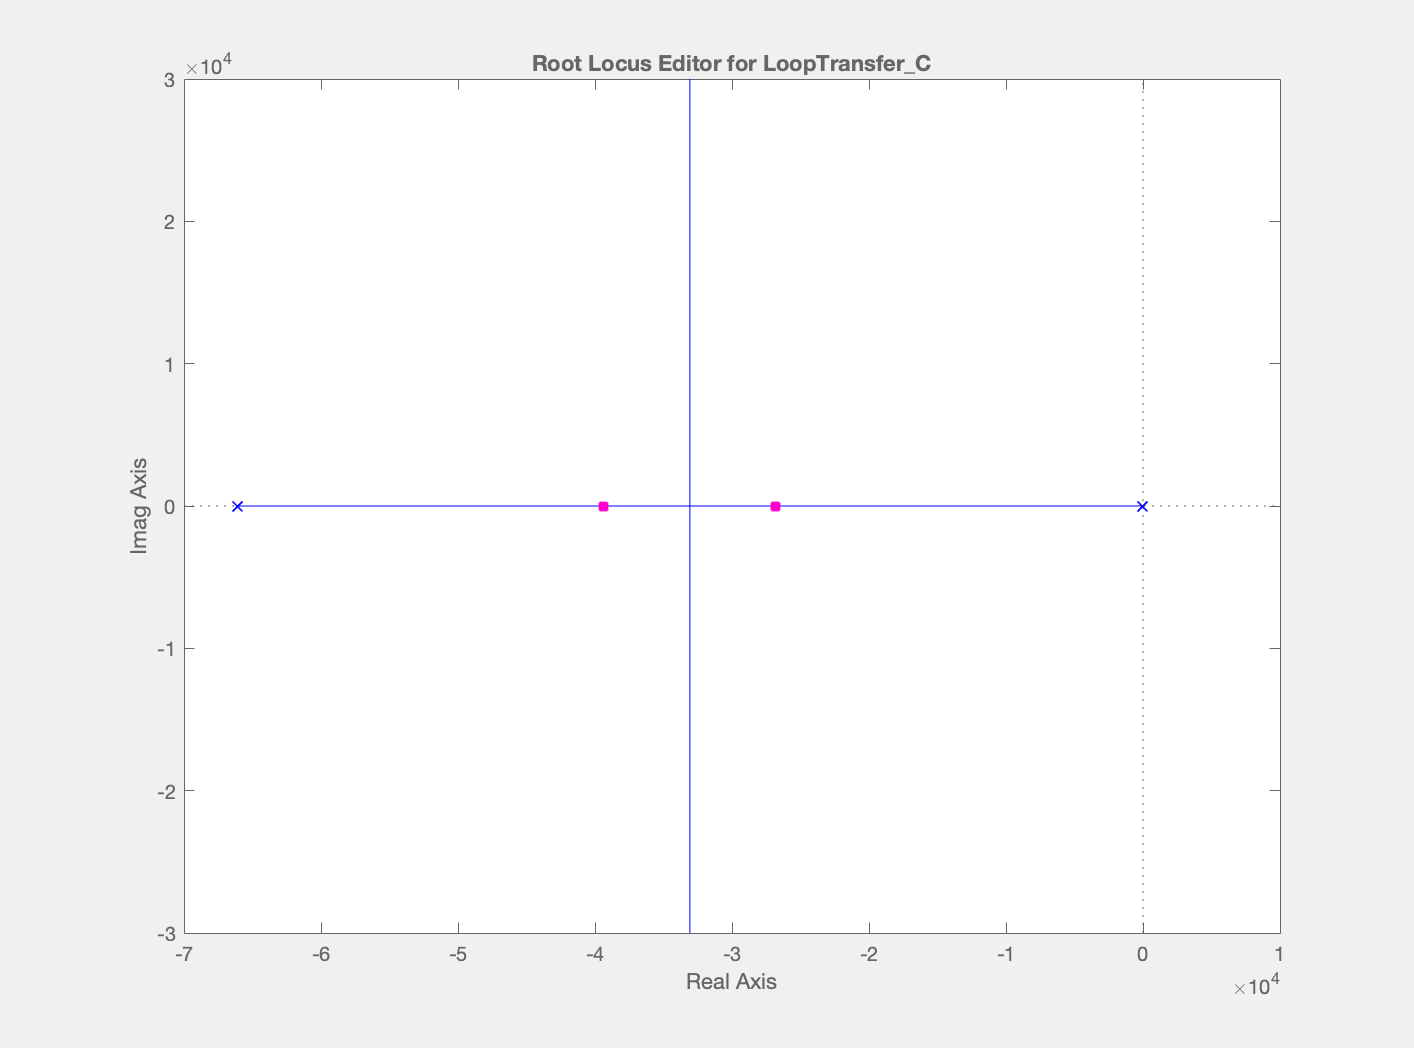

s = tf('s');
P_motor = lambda/((J*s+b)*(L*s+R)+lambda^2);
%opt = stepDataOptions('StepAmplitude', 6);
%controlSystemDesigner('rlocus', P_motor)